# **RS-MILP-02-01: Configure BCD(Block Coordinate Descent) for distributed approach of MILP**

**University of Texas at Austin**

**Department of Aerospace Engineering and Engineering Mechanics**

**Hongseok Kim**

## **1. Generate A matrix from contact chart**

clear;
clc;


addpath('/Library/gurobi1300/macos_universal2/matlab')
savepath

addpath ~/Desktop/Redstone_MILP/RS_MILP_01_Config_MILP/
load('EOIR_48_SATs_12_Orbit_Planes_98_inc_7days_access_interval.mat','EOIR_access_interval')


% 기준 시각 정의

T = EOIR_access_interval;

t0 = datetime(2030, 1, 1, 0, 0, 0,'TimeZone','UTC');

% --- Source / Target을 string으로 통일 ---
src = string(T.Source);
tgt = string(T.Target);

% --- Ground 번호 추출 ---
gTok = regexp(src, 'Ground[_\s]*Point[_\s]*(\d+)', 'tokens', 'once');
groundNum = cellfun(@(c) str2double(c{1}), gTok);

% --- Satellite 번호 추출 ---
sTok = regexp(tgt, '(?i)SAT[^0-9]*(\d+)', 'tokens', 'once');
satNum = cellfun(@(c) str2double(c{1}), sTok);

% --- Start / End → datetime ---
st = T.StartTime;
en = T.EndTime;

if ~isdatetime(st)
    st = datetime(string(st), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end
if ~isdatetime(en)
    en = datetime(string(en), 'InputFormat','dd-MMM-yyyy HH:mm:ss');
end

% --- 중간 시각 ---
midTime = st + (en - st)/2;

% --- 기준 시각 대비 초(second) 차이 → integer ---
timeSec = seconds(midTime - t0);
timeSec = double(round(timeSec));   % 정수화 (필요시 floor / ceil로 변경 가능)


contact_index = (1:length(st))';

% --- 최종 3-column matrix ---
A_matrix = [double(satNum), double(groundNum), timeSec, contact_index];

A_matrix = sortrows(A_matrix, 3);

A_matrix = A_matrix(1:1000,:);
Original_A = T(A_matrix(:,4),:);


N = length(A_matrix(:,1));

## 2. Extract Key parameters from A matrix

t = A_matrix(:,3);

% Satellite Cadence Constraint
tau = 20;

% Number of SATs
p = 48;

% Number of GSs
q = 54;

% Total number of contact
N = length(A_matrix(:,1));

% Number of contact for each SAT
S_i_vec = zeros(p,1);

for sat_index = 1:p
    S_i_vec(sat_index) = nnz(A_matrix(:,1) == sat_index);
end

% Number of contact for each GS
G_j_vec = zeros(q,1);
for gs_index = 1:q
    G_j_vec(gs_index) = nnz(A_matrix(:,2) == gs_index);
end

## 3. Selection matrix generation from given constant parameters

### 3.1. $E_{S_i }^1$: Selection matrix from A-matrix to each satellite's contact sequence

E1_Si = struct();

for i = 1:p

E1_Si_mat = zeros(S_i_vec(i),N);

a_i = find(A_matrix(:,1) == i);

  for j = 1:length(a_i)
      E1_Si_mat(j, a_i(j)) = 1;
  end

  E1_Si.(['sat',num2str(i)]) = E1_Si_mat;

end

### 3.2. $E_{S_i ,x}^2 \;,E_{S_{i,t} }^2$: Selection matrix for $\Delta t$ of each satelltite from $\left|S_i \right|$

E2_Si_x = struct();

for i = 1:p
    E2_Si_x_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_x_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_x_alpha(:,alpha) = 1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_x_mat = [E2_Si_x_mat;E2_Si_x_alpha]; 
    end
   if isempty(E2_Si_x_mat)
     E2_Si_x_mat = 0;
   end
   E2_Si_x.(['sat',num2str(i)]) = E2_Si_x_mat;
end


E2_Si_t = struct();

for i = 1:p
    E2_Si_t_mat = [];
    for alpha = 1:S_i_vec(i)-1
        E2_Si_t_alpha = zeros(S_i_vec(i)-alpha, S_i_vec(i));
        E2_Si_t_alpha(:,alpha) = -1;
        for beta = alpha+1:S_i_vec(i)
            E2_Si_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Si_t_mat = [E2_Si_t_mat;E2_Si_t_alpha]; 
    end
   if isempty(E2_Si_t_mat)
     E2_Si_t_mat = 0;
   end
    E2_Si_t.(['sat',num2str(i)]) = E2_Si_t_mat;
end

### 3.3. $E_{G_j }^1$: Selection matrix from A-matrix to each Ground Point's revisit sequence

E1_Gj = struct();

for j = 1:q
    E1_Gj_mat = zeros(G_j_vec(j)+2, N+2);

    E1_Gj_mat(1,1) = 1;
    b_j = find(A_matrix(:,2) == j);

    for alpha = 1:length(b_j)
        E1_Gj_mat(alpha+1, b_j(alpha)+1) = 1;
    end
    E1_Gj_mat(G_j_vec(j)+2, N+2) = 1;
    E1_Gj.(['gs', num2str(j)]) = E1_Gj_mat;
end

### 3.4. $E_{G_{j,x} }^2 \;,E_{G_{j,t} }^2$: Selection matrix for $\Delta t$ of each GS from $\left|G_j \right|$

E2_Gj_x = struct();

for j = 1:q
    E2_Gj_x_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_x_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_x_alpha(:,alpha) = 1;
        for beta = alpha+1:G_j_vec(j)+2
            if alpha + 1 <= beta-1
               E2_Gj_x_alpha(beta-alpha, alpha+1:beta-1) = -1; 
            end
            E2_Gj_x_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_x_mat = [E2_Gj_x_mat;E2_Gj_x_alpha]; 
    end
   if isempty(E2_Gj_x_mat)
     E2_Gj_x_mat = 0;
   end
   E2_Gj_x.(['gs',num2str(j)]) = E2_Gj_x_mat;
end

E2_Gj_t = struct();

for j = 1:q
    E2_Gj_t_mat = [];
    for alpha = 1:G_j_vec(j)+1
        E2_Gj_t_alpha = zeros(G_j_vec(j)+2-alpha, G_j_vec(j)+2);
        E2_Gj_t_alpha(:,alpha) = -1;
        for beta = alpha+1:G_j_vec(j)+2
            E2_Gj_t_alpha(beta-alpha,beta) = 1;
        end
     E2_Gj_t_mat = [E2_Gj_t_mat;E2_Gj_t_alpha]; 
    end
   if isempty(E2_Gj_t_mat)
     E2_Gj_t_mat = 0;
   end
   E2_Gj_t.(['gs',num2str(j)]) = E2_Gj_t_mat;
end

### 4. Derivation of $A,b,C,d,E,f,G$ revisit time problem to MILP

#### 4.1 $A,b$ for $L_1$ problem , $A_{s_i }$, $b_{s_i }$ for BCD/ADMM , $P-\textrm{matrix}$ for Permutation, $U,V$ for sizing index

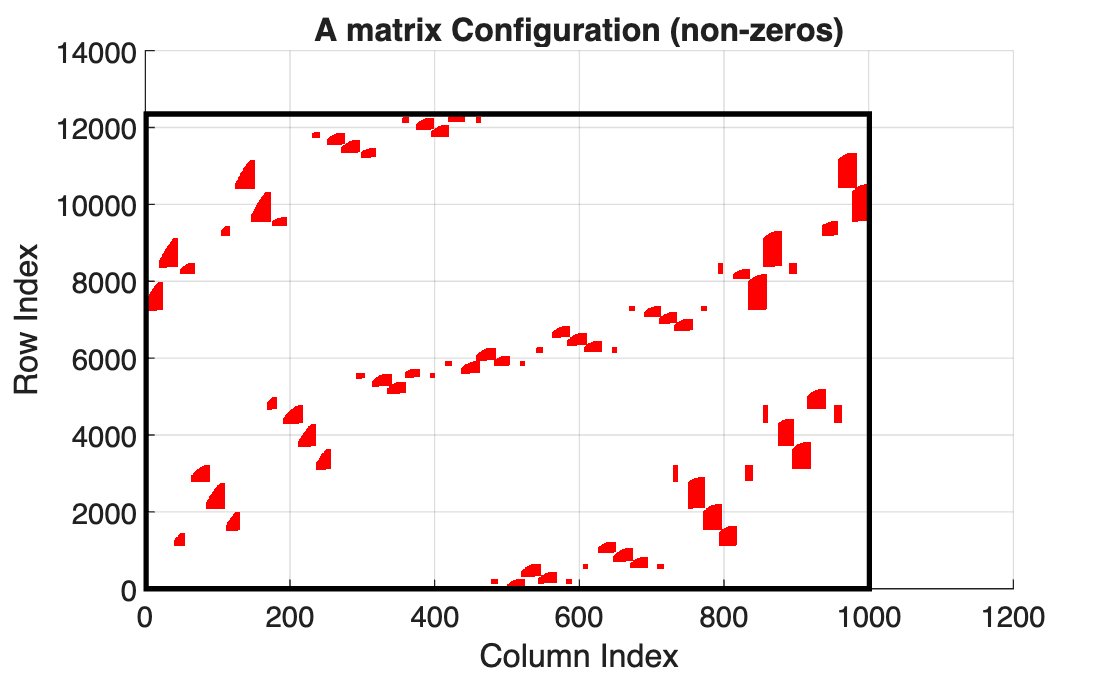

A = [];
b_mat = [];
P_matrix_transpose = [];

U = 0;
V = 0;

for i = 1:p
  if isempty(E1_Si.(['sat', num2str(i)])) 
  continue;
  end

  A_i = E2_Si_x.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  A = [A;A_i];
  b_i_mat =  E2_Si_t.(['sat', num2str(i)]) * E1_Si.(['sat', num2str(i)]);
  b_mat = [b_mat; b_i_mat];


  A_si_info.(['sat', num2str(i)]) = E2_Si_x.(['sat', num2str(i)]);
  b_si_info.(['sat', num2str(i)]) = ones(length(b_i_mat(:,1)),1) + 1/tau * b_i_mat* A_matrix(:,3);

  P_matrix_transpose = [P_matrix_transpose; E1_Si.(['sat', num2str(i)])];

  E1_si = E1_Si.(['sat', num2str(i)]);
  S_i_info.(['sat', num2str(i)]) = length(E1_si(:,1));

  U_i_info.(['sat', num2str(i)]) = U;
  V_i_info.(['sat', num2str(i)]) = N - length(E1_si(:,1)) - U;
  U = U + length(E1_si(:,1));

end



b = ones(length(b_mat(:,1)),1) + 1/tau * b_mat * A_matrix(:,3);
P_matrix = P_matrix_transpose';


[A_row, A_col] = find(A==1);
figure;
hold on
scatter(A_col,A_row,'r','.')
rectangle('Position',[1 1 max(A_col), max(A_row)], ...
          'EdgeColor','k', ...
          'LineWidth',2);
title('A matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on

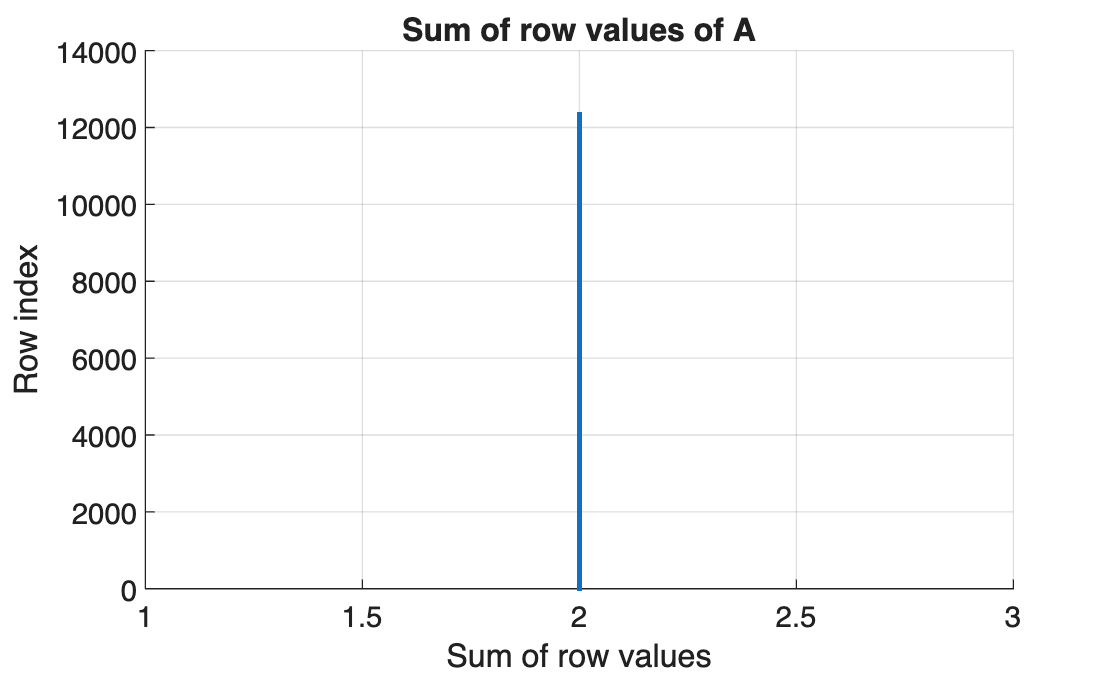



row_sum = sum(A, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of A','FontSize',12,'FontWeight','bold')

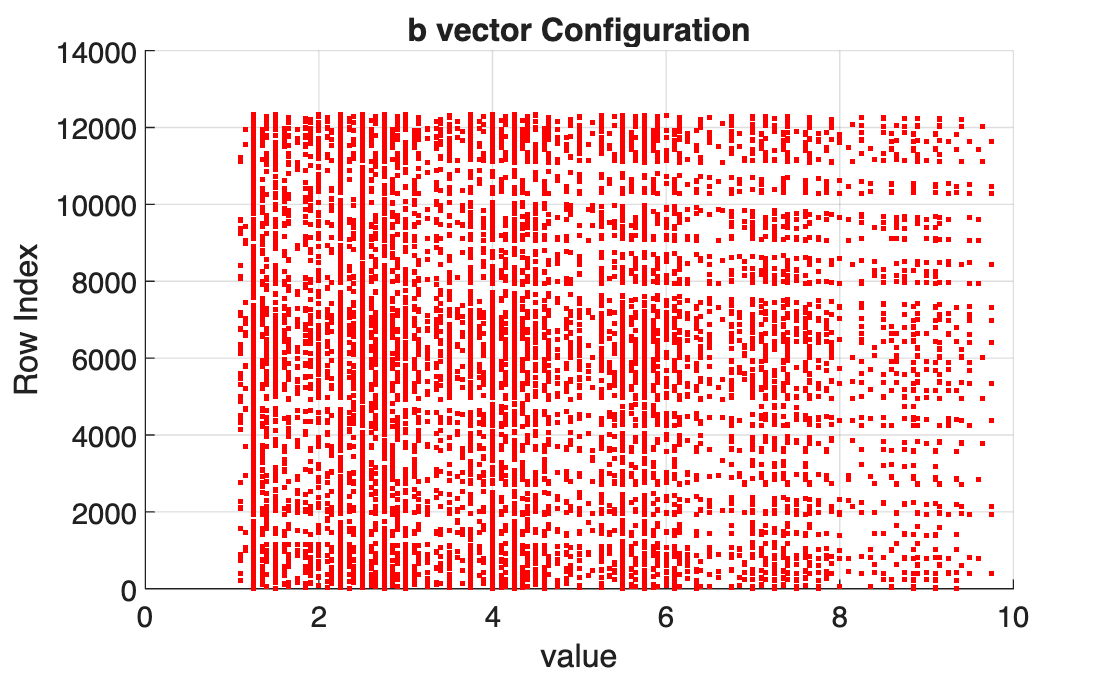



figure;
scatter(b,1:length(b),'r','.')
title('b vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
xlim([0,10])
grid on

#### 4.2 $C,d$ for $L_{\infty }$ problem

C = [];
d = [];

t = A_matrix(:,3);                  % (N×1) time vector in seconds (already prepared)
t_aug = [min(A_matrix(:,3)); t; max(A_matrix(:,3))+1];        % (N+2 × 1)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % =========================
    % Build C_j  (constant)
    % =========================
    % D_j = diag( E2t*E1 * t_aug )   (vector -> diagonal matrix)
    Dj_vec = (E2t * E1) * t_aug;           % (#rows_j × 1)
    Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec));  % sparse diag is safer

    % P = [0_{1×N}; I_{N×N}; 0_{1×N}]  -> (N+2 × N)
    N = length(t);
    P = [zeros(1,N); speye(N); zeros(1,N)];

    % C_j = D_j * (E2x*E1) * P
    Cj = Dj * (E2x * E1) * P;

    % =========================
    % Build d_j  (constant)
    % =========================
    % v = [1; 0_{N×1}; 1] - 1  = [0; -1...; 0]
    v = [1; zeros(N,1); 1];          % (N+2 × 1)

    % d_j = D_j * (E2x*E1) * v
    dj = Dj * ((E2x * E1) * v - ones(length(Dj(:,1)),1));

    % --- stack ---
    C = [C; Cj];
    d = [d; dj];
end


% [C_row, C_col] = find(C~=0);
% 
% figure;
% scatter(C_row, C_col,'r','.')
% grid on

#### 4.3 $E,f,G$ for $L_2$ Optimization problem

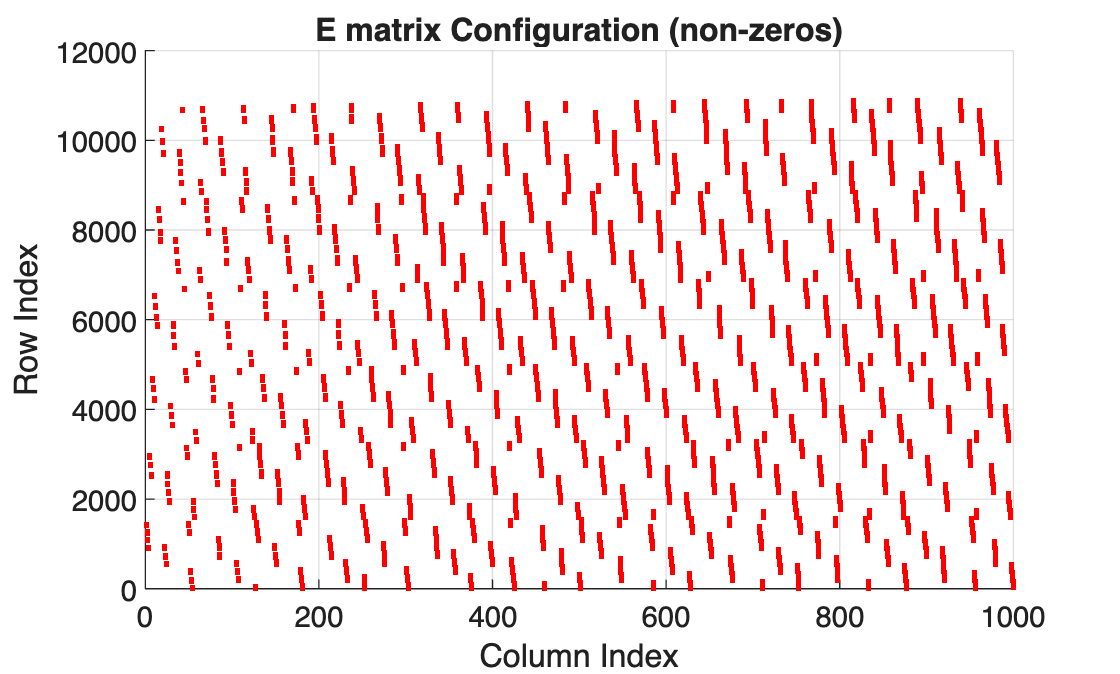

% =========================
% Build E, f, G  (2nd image)
% =========================

E_ori = [];
F = [];

t = A_matrix(:,3);                       % (N×1)
N = length(t);

t_aug = [min(t); t; max(t)+1];                % (N+2 × 1), same as your code

% P = [0_{1×N}; I_N; 0_{1×N}]  -> (N+2 × N)
P = [zeros(1,N); speye(N); zeros(1,N)];

% this is the (N+2 × 1) vector [1; 0_N; 1]
one_aug = [1; zeros(N,1); 1];

% For G, we will build the stacked matrix Bt = [E2t*E1; ...] first (optional),
% or directly build gvec = Bt*t_aug.
gvec = [];   % = Bt * t_aug  (will be stacked across j)

for j = 1:q
    key = ['gs', num2str(j)];

    if isempty(E1_Gj.(key))
        continue;
    end

    % --- shorthand ---
    E1  = E1_Gj.(key);        % selection matrix for this ground
    E2x = E2_Gj_x.(key);
    E2t = E2_Gj_t.(key);

    % Common blocks
    Sx = (E2x * E1);          % (#rows_j × (N+2))
    St = (E2t * E1);          % (#rows_j × (N+2))

    % -------------------------
    % E_j = Sx * P    (constant)
    % -------------------------
    Ej = Sx;              % (#rows_j × N)
    E_ori  = [E_ori; Ej];

    % -------------------------
    % f_j = Sx]
    % -------------------------
    Fj = Sx;        % (#rows_j × 1)
    F  = [F; Fj];

    % -------------------------
    % gvec_j = St * t_aug
    % -------------------------
    gvec_j = St * t_aug;      % (#rows_j × 1)
    gvec   = [gvec; gvec_j];
end

% Dj = spdiags(Dj_vec, 0, length(Dj_vec), length(Dj_vec)); 

E = E_ori * P;
f_vector = F * one_aug;

% -------------------------
% G = gvec * gvec'
% -------------------------
% WARNING: this can be very large/dense if gvec is long.
% If you only need y'*G*y, note that y'*(gvec*gvec')*y = (gvec'*y)^2.
G = spdiags(gvec, 0, length(gvec), length(gvec));   % (M×M)


[E_one_col, E_one_row] = find(E == 1);
[E_minus_one_col, E_minus_one_row] = find(E == -1);

figure;
hold on
scatter(E_minus_one_row, E_minus_one_col,'blue','.')
scatter(E_one_row, E_one_col,'red','.')


grid on
title('E matrix Configuration (non-zeros)','FontSize',12,'FontWeight','bold')
xlabel('Column Index')
ylabel('Row Index')
grid on

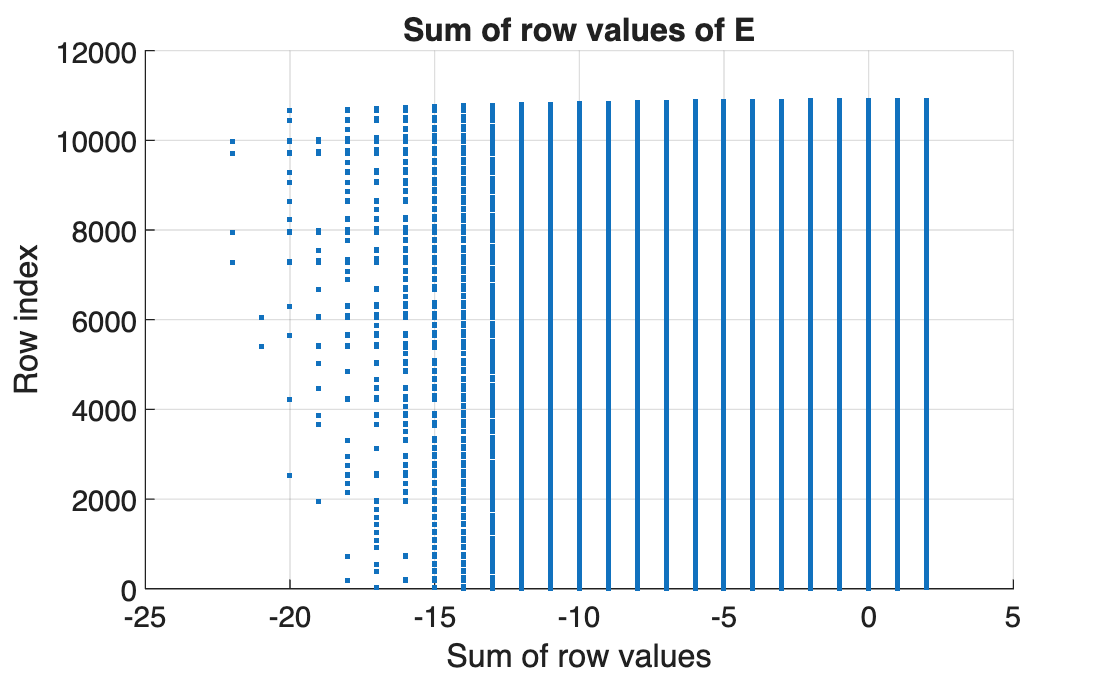

row_sum = sum(E, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_sum,1:length(row_sum),'.');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of row values')
title('Sum of row values of E','FontSize',12,'FontWeight','bold')

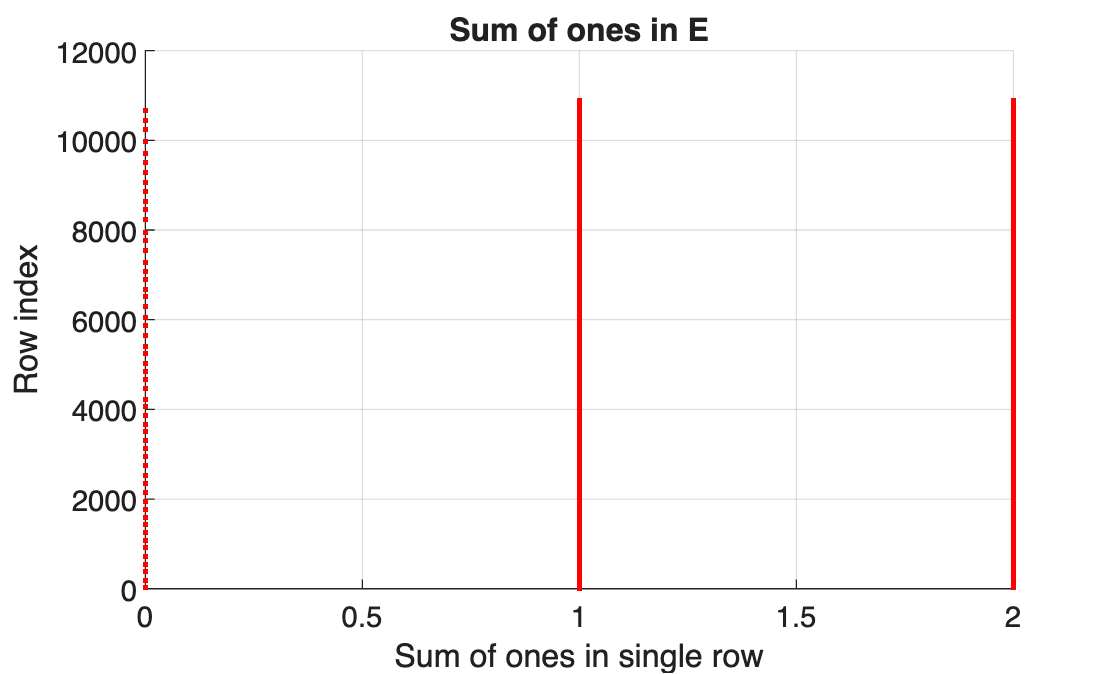



row_one_sum = sum(E == 1, 2);        % 각 row의 합 (N×1)
figure;
scatter(row_one_sum,1:length(row_one_sum),'.','r');        % x축은 자동으로 row index (1:N)
grid on
ylabel('Row index')
xlabel('Sum of ones in single row')
title('Sum of ones in E','FontSize',12,'FontWeight','bold')

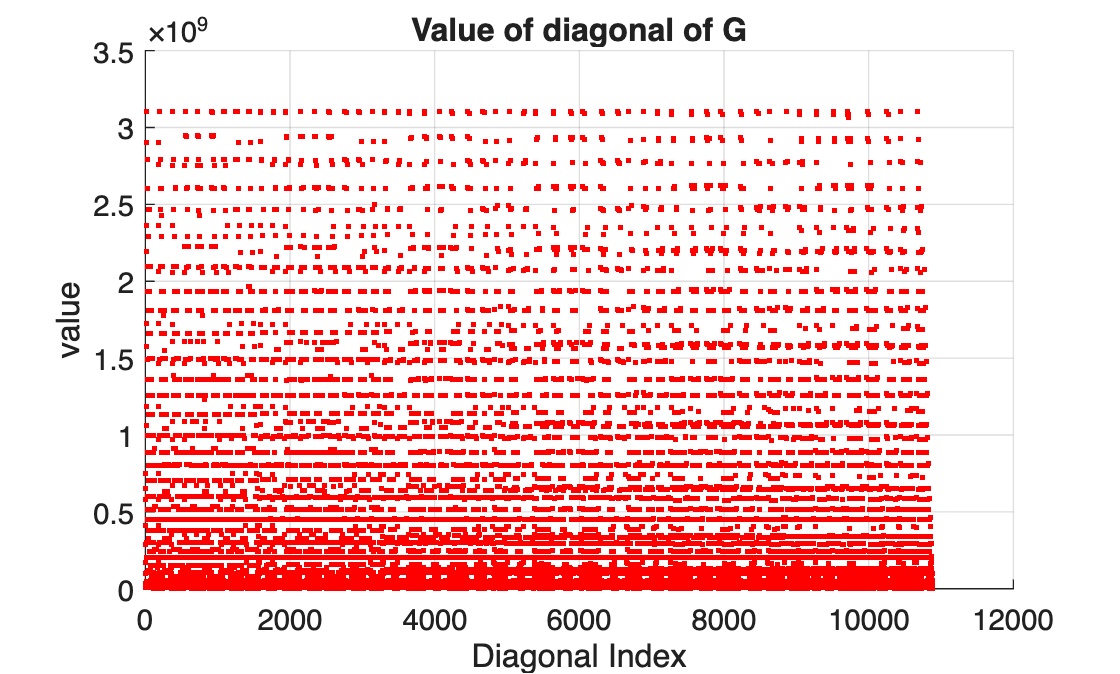


scatter(1:length(gvec),gvec.^2,'r','.')
title('Value of diagonal of G','FontSize',12,'FontWeight','bold');
ylabel('value')
xlabel('Diagonal Index')
grid on

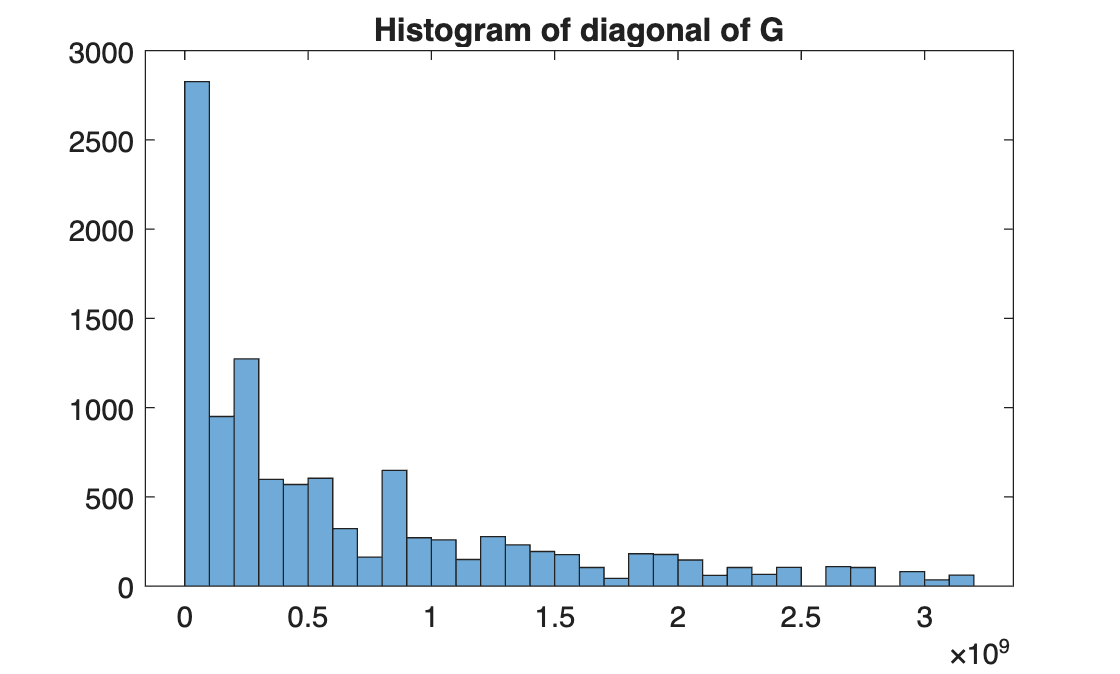


figure;
histogram(gvec.^2)
title('Histogram of diagonal of G','FontSize',12,'FontWeight','bold');

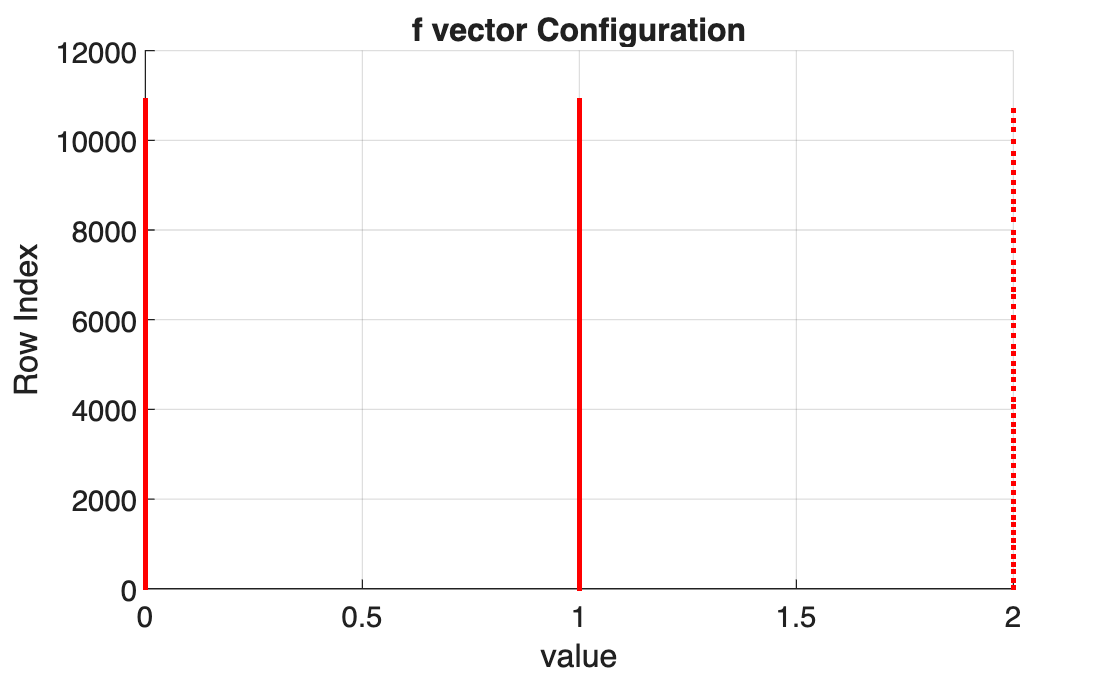


scatter(f_vector,1:length(f_vector),'r','.')
title('f vector Configuration','FontSize',12,'FontWeight','bold')
xlabel('value')
ylabel('Row Index')
grid on

## 5. Solving MILP by BCD

### 5.1 BCD: Block Coordinate Descent

%% =========================
%  BCD for (MIQP/MILP-like) with z >= E*P*xbar + f - 1
%  - each agent i updates x_{s_i} (binary) sequentially
%  - z is continuous and is re-optimized in each local subproblem
%% =========================

% ---- user provided initializations (keep) ----
x = zeros(length(A_matrix(:,1)),1);
z = zeros(length(f_vector),1);

x_history_BCD = [];
z_history_BCD = [];

% ---- BCD options ----
maxOuterIters = 50;          % outer sweeps (full i=1..p)
tol_x_change  = 0;           % since binary, exact equality check is fine
verbose       = 1;

% ---- precompute constant matrices ----
% P_matrix: permutation such that x = P * [x_s1; ...; x_sp]
% EP = E * P  (used in all agents)
EP = E * P_matrix;

% ---- build block index map (idx_i for each agent) ----
% You already have:
%   U = sum_{j<i} |S_j|,  S_i is list (or just length defines block size)
% We'll build idx_i = (U+1):(U+|S_i|)
idx_block = cell(p,1);
for i = 1:p
    if isempty(E1_Si.(['sat', num2str(i)])) 
        idx_block{i} = [];
        continue;
    end
    U = U_i_info.(['sat', num2str(i)]);
    S_i = S_i_info.(['sat', num2str(i)]);
    nSi = length(S_i);
    idx_block{i} = (U+1):(U+nSi);
end

BCD_handle = 1;
outerIter  = 0;

while BCD_handle == 1
    outerIter = outerIter + 1;
    if outerIter > maxOuterIters
        if verbose, fprintf('[BCD] Reached maxOuterIters=%d\n', maxOuterIters); end
        break;
    end

    x_old_sweep = x;
    z_old_sweep = z;

    for i = 1:p
        % skip empty agent
        if isempty(E1_Si.(['sat', num2str(i)]))
            continue;
        end

        % ----- snapshot current iterate -----
        x_k = x;
        z_k = z; %#ok<NASGU>  % (kept if you want warm-start logic)

        % ----- local constraints -----
        A_si = A_si_info.(['sat', num2str(i)]);
        b_si = b_si_info.(['sat', num2str(i)]);

        % ----- stacked vector at k: xbar^k = P' * x^k -----
        xbar_k = P_matrix' * x_k;

        % ----- identify current local block -----
        idx_i  = idx_block{i};
        x_si_k = E1_Si.(['sat', num2str(i)]) * x_k;       % this is the "current" local block

        % ----- coupling base term: base0 = EP*xbar_k + f - 1 -----
        base0  = EP * xbar_k + f_vector - 1;

        % ----- the only part that multiplies x_si variable -----


        U = U_i_info.(['sat', num2str(i)]);
        V   = V_i_info.(['sat', num2str(i)]);
        S_i = S_i_info.(['sat', num2str(i)]);
        EP_i = EP(:, (U+1):(U+S_i));          % == EP * J_i

        J_i = sparse(N, S_i);              % (U+|S_i|+V) x |S_i|
        J_i(U+1:U+S_i, :) = speye(S_i);    % middle block = I_|S_i|

        % ----- Build and solve local MIQP/MILP -----
        % Variables: [x_si; z]
        %   x_si in {0,1}^{|S_i|},  z in R^{m}, typically with z >= 0
        %
        % Constraints:
        %   (1) A_si * x_si <= b_si
        %   (2) z >= base0 + EP_i*(x_si - x_si_k)
        %       -> -z + EP_i*x_si <= -(base0 - EP_i*x_si_k)
        %   (3) z >= 0   (recommended if z is slack-like)
        %
        % Objective:
        %   min sum_j G_j * z_j^2   (i.e., z' diag(G) z)
        %
        % NOTE: set Gvec (length m) as your diag weights.
        % If you have G as matrix, pass diag(G).

        % choose your weight vector for quadratic objective:
        % - if you already have G as vector: use it directly
        % - if you have G as diagonal matrix: use diag(G)
        g = gvec.^2;

        % solve local subproblem with Gurobi MIQP
        params = struct();
        params.OutputFlag = 0;   % set 1 for debugging

        sol = solve_local_milp_gurobi(A_si, b_si, EP_i, base0, x_si_k, g, params);

        % if infeasible or failed, skip update gracefully
        if ~sol.success
            if verbose
                fprintf('[BCD] sat%d local solve failed (status=%s). Keep x,z.\n', i, sol.status);
            end
            continue;
        end

        x_si_new = sol.x_si;
        z_new    = sol.z;

        % ----- write back to global x via stacked vector -----
        xbar_new = xbar_k + J_i* (x_si_new - x_si_k);
        x = P_matrix * xbar_new;
        z = z_new;

        % history
        x_history_BCD = [x_history_BCD, x]; %#ok<AGROW>
        z_history_BCD = [z_history_BCD, z]; %#ok<AGROW>
    end

    % ----- stopping check (end of sweep) -----
    if isequal(x, x_old_sweep) && norm(z - z_old_sweep, Inf) <= 1e-12
        if verbose
            fprintf('[BCD] Converged at outerIter=%d (no change after full sweep)\n', outerIter);
        end
        break;
    else
        if verbose
            dx = nnz(x ~= x_old_sweep);
            dz = norm(z - z_old_sweep, Inf);
            fprintf('[BCD] outerIter=%d done. nnz(dx)=%d, ||dz||_inf=%.3e\n', outerIter, dx, dz);
        end
    end
end

[BCD] outerIter=1 done. nnz(dx)=359, ||dz||_inf=1.000e+00
[BCD] outerIter=2 done. nnz(dx)=96, ||dz||_inf=1.000e+00
[BCD] outerIter=3 done. nnz(dx)=34, ||dz||_inf=1.000e+00
[BCD] outerIter=4 done. nnz(dx)=2, ||dz||_inf=1.000e+00


[BCD] Converged at outerIter=5 (no change after full sweep)


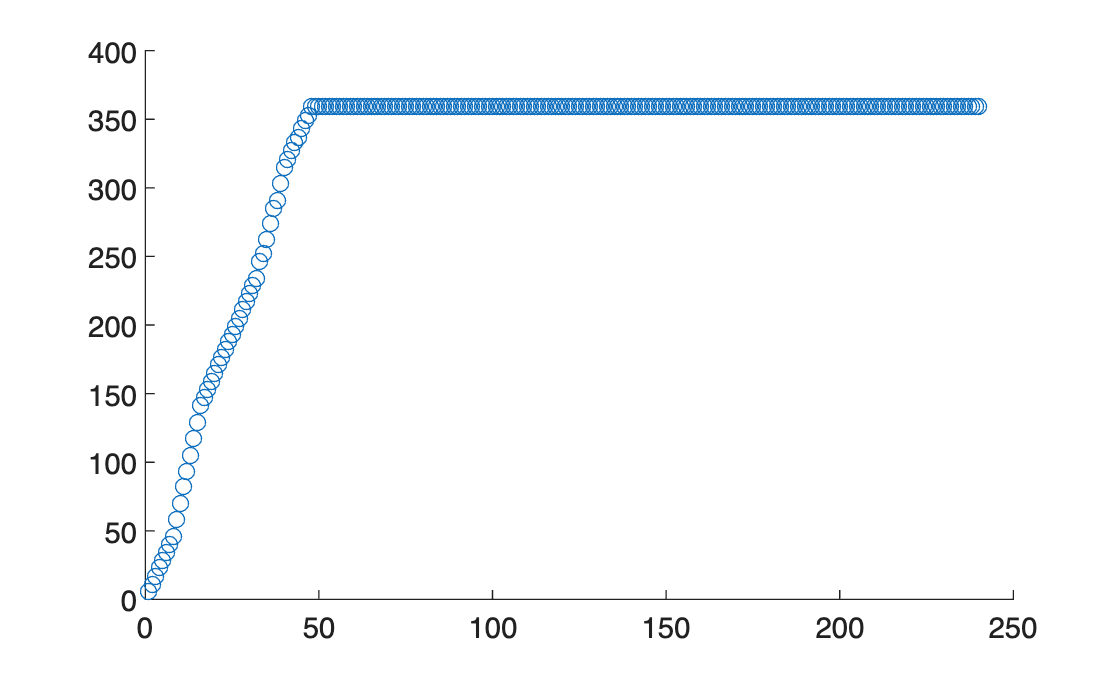

row_sum_x = sum(x_history_BCD, 1);

scatter(1:length(row_sum_x), row_sum_x)

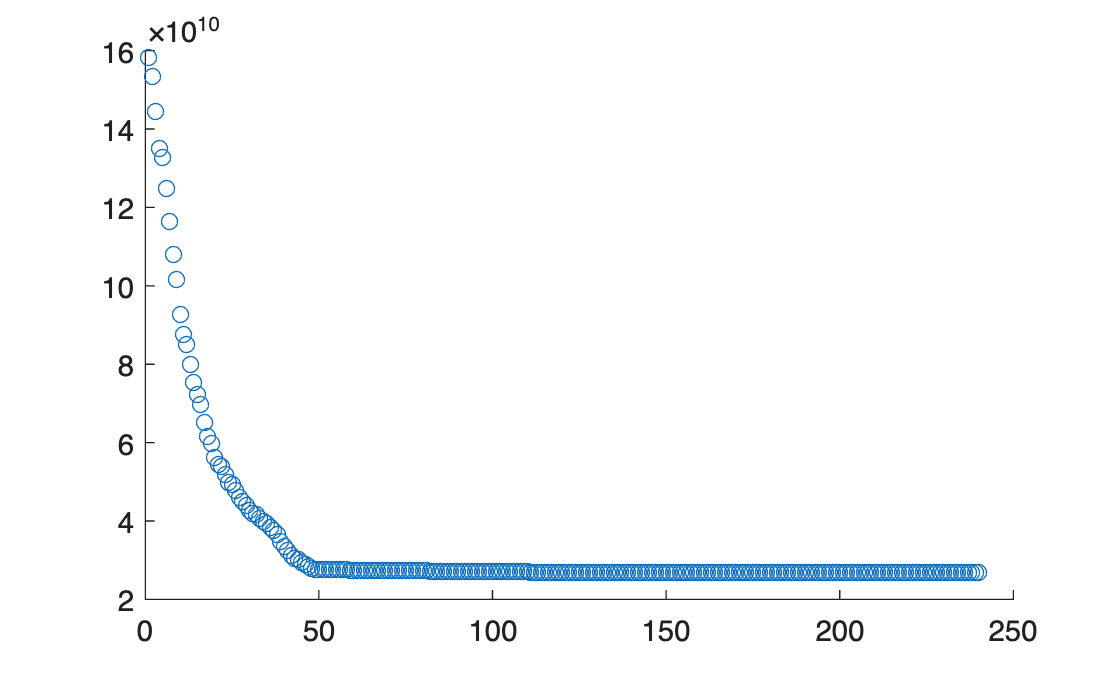


obj_history = g.' * z_history_BCD;   % 1 x K row vector

scatter(1:length(obj_history), obj_history)

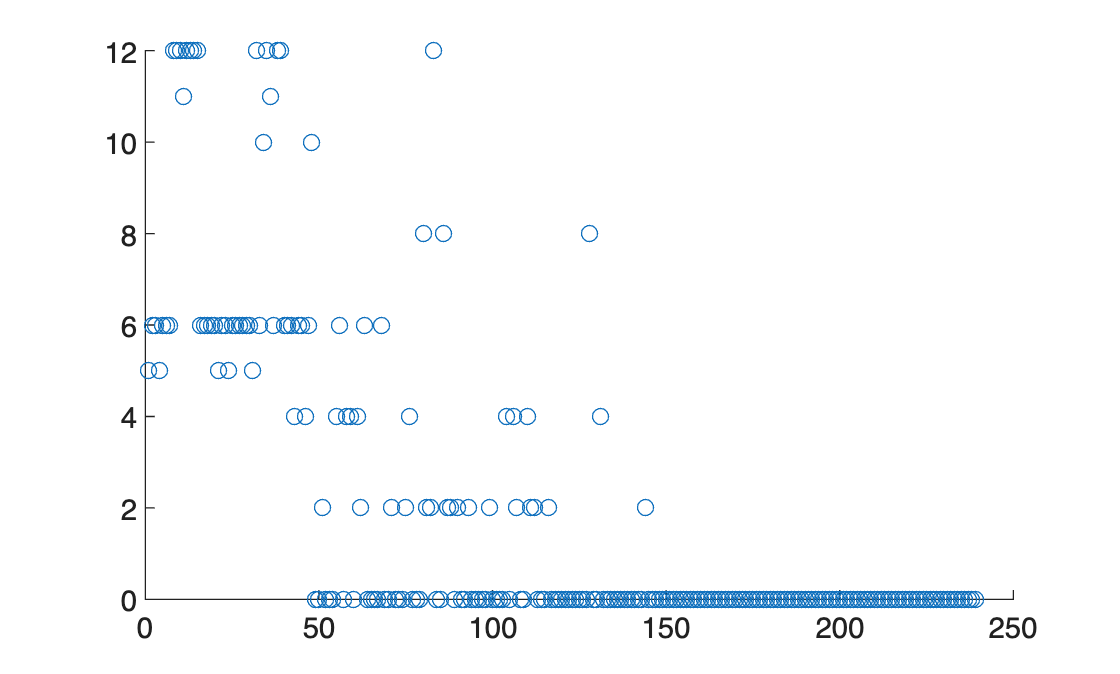




x_opt_L2 = x_history_BCD(:,end);   % binary
row_index_L2 = x_opt_L2 .* A_matrix(:,4);
row_index_L2 = row_index_L2(row_index_L2 ~= 0);

Original_A_L2 = T(row_index_L2,:);
A_matrix_L2   = A_matrix(x_opt_L2 == 1,:);

N = size(x_history_BCD,2);
hamming_row = zeros(N-1,1);

for i = 1:N-1
    hamming_row(i) = sum(abs(x_history_BCD(:,i+1) - x_history_BCD(:,i)));
end

scatter(1:length(hamming_row), hamming_row)

function sol = solve_local_milp_gurobi(A_si, b_si, EP_i, base0, x_si_k, g, params)
% Local MILP:
%   min   g' z
%   s.t.  A_si * x_si <= b_si
%         z >= base0 + EP_i*(x_si - x_si_k)
%         z >= 0
%         x_si in {0,1}^{nSi}
%
% Variables: v = [x_si; z]

    sol = struct('success', false, 'x_si', [], 'z', [], 'status', '');

    nSi = size(A_si,2);
    m   = length(base0);

    if length(g) ~= m
        error('Length of g must match length(base0) = #z.');
    end

    nvar = nSi + m;
    model.modelsense = 'min';

    % ----- linear objective: g' z -----
    model.obj = [zeros(nSi,1); g(:)];

    % ----- variable types -----
    model.vtype = [repmat('B', nSi, 1); repmat('C', m, 1)];

    % ----- bounds -----
    model.lb = [zeros(nSi,1); zeros(m,1)];
    model.ub = [ones(nSi,1);  inf(m,1)];

    % ----------------------------
    % Constraints
    % (1) A_si x_si <= b_si
    % (2) z >= base0 + EP_i*(x_si - x_si_k)
    %     -> -z + EP_i*x_si <= -(base0 - EP_i*x_si_k)
    % ----------------------------
    % (1)
    A1 = sparse(size(A_si,1), nvar);
    A1(:,1:nSi) = sparse(A_si);
    rhs1 = b_si(:);
    sense1 = repmat('<', size(A_si,1), 1);

    % (2)
    A2 = sparse(m, nvar);
    A2(:,1:nSi)     = sparse(EP_i);
    A2(:,nSi+1:end) = -speye(m);

    rhs2 = -(base0(:) - EP_i * x_si_k(:));
    sense2 = repmat('<', m, 1);

    model.A     = [A1; A2];
    model.rhs   = [rhs1; rhs2];
    model.sense = [sense1; sense2];

    % params
    if nargin < 7 || isempty(params)
        params = struct();
    end

    % solve
    try
        result = gurobi(model, params);
    catch ME
        sol.status = ['gurobi_error: ', ME.message];
        return;
    end

    sol.status = result.status;

    if strcmpi(result.status,'OPTIMAL') || strcmpi(result.status,'SUBOPTIMAL')
        v = result.x;
        sol.x_si = v(1:nSi);
        sol.z    = v(nSi+1:end);
        sol.success = true;
    end
end


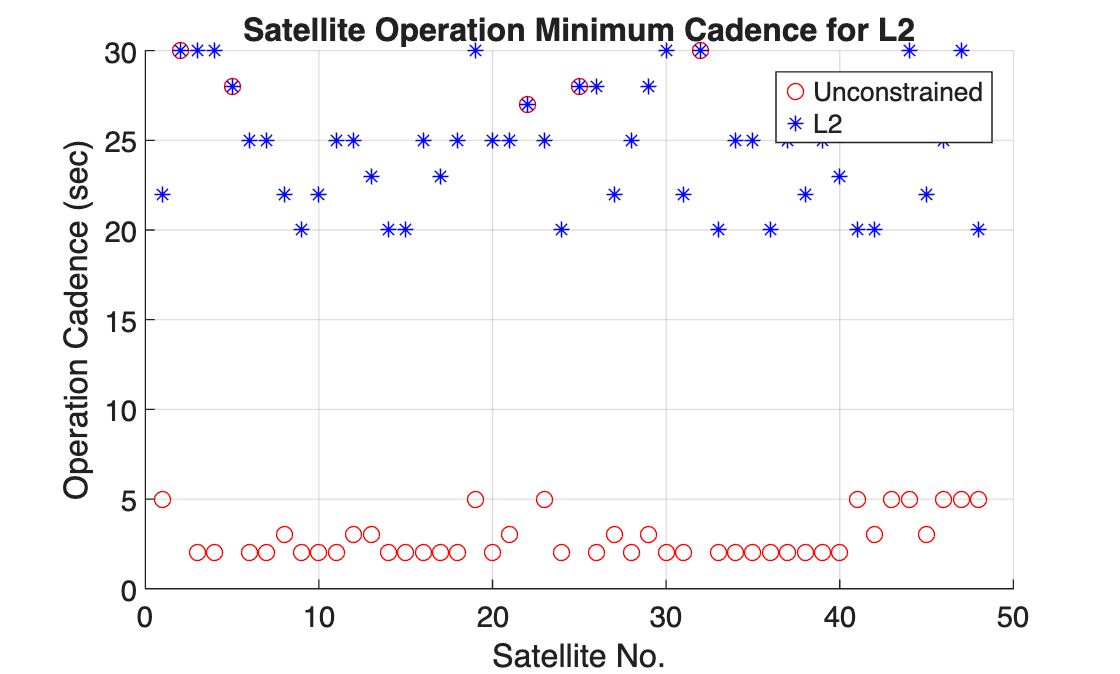

A_matrix_result = A_matrix;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_original = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);
      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_matrix_original(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end

    
A_matrix_result = A_matrix_L2;

active_satellites = unique(A_matrix_result(:,1));
cadence_matrix_L2 = zeros(length(active_satellites),4);

    for index = 1:length(active_satellites)
      sat_index = active_satellites(index);
      % satellite_cadence_info.(['sat',num2str(sat_index)]) = A_matrix_result(A_matrix_result(:,1) == sat_index,:);     
      satellite_cadence = A_matrix_result(A_matrix_result(:,1) == sat_index,:);

      if isscalar(satellite_cadence(:,1))
         continue;
      end

      cadence_info = zeros(length(satellite_cadence(:,1))-1,1);
      for i = 1:length(cadence_info(:,1))
         cadence_info(i) = satellite_cadence(i+1,3) - satellite_cadence(i,3);
      end

      cadence_matrix_L2(index,:) = [sat_index, max(cadence_info), min(cadence_info), mean(cadence_info)];
    end
    

cadence_matrix_L2 = cadence_matrix_L2(cadence_matrix_L2(:,3)~=0,:);


figure;
hold on
scatter(cadence_matrix_original(:,1),cadence_matrix_original(:,3),'o','red')
scatter(cadence_matrix_L2(:,1),cadence_matrix_L2(:,3),'*','blue')
title('Satellite Operation Minimum Cadence for L2','FontSize',12,'FontWeight','bold')
legend('Unconstrained','L2')
xlabel('Satellite No.')
ylabel('Operation Cadence (sec)')
grid on

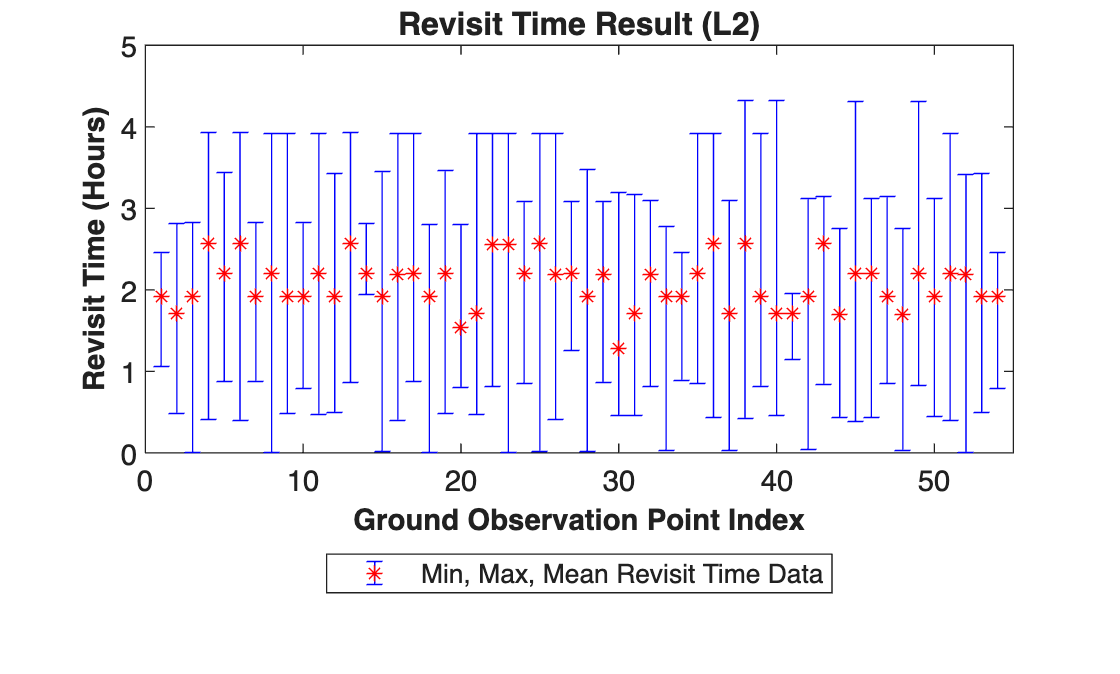


 % Extract Ground Point Tables
  T = Original_A_L2;

    % Source 열에서 고유 값 추출
    sources = unique(T.Source);

    % Revisit Time Matrix (Min / Max / Mean) 생성
    Revisit_Matrix = zeros(length(sources),3);
    revisit_time_vector_combined = [];

    t0 = datetime(2030, 1, 1, 0, 0, 0,'TimeZone','UTC');
    t_start = t0 + seconds(min(A_matrix(:,3)));
    t_end = t0 + seconds(max(A_matrix(:,3))+1);

    % 각각의 Source 별로 테이블을 분리하여 저장
    for i = 1:length(sources)
        src = sources{i};

        % Source 값이 같은 행들만 추출
        subTable = T(strcmp(T.Source, src), :);
        subTable_sorted = sortrows(subTable,4,"ascend");


        % 동적으로 변수 생성 (예: Ground_Point_1_Table)
        varName = sprintf('%s_Table', src);
        % assignin('base', varName, subTable_sorted);
        contact_tables.(sprintf('%s_Table', src)) = subTable_sorted;

        % 기존 row에 start 및 endtime 추가
        row0 = subTable_sorted(1,:);
        
        % -------------------------
        % 윗줄 (t_start)
        % -------------------------
        row_top = row0;
        row_top.IntervalNumber = NaN;      % 필요 없으면 NaN
        row_top.StartTime = t_start;
        row_top.EndTime   = t_start;
        row_top.Duration  = 0;
        row_top.StartOrbit = 0;
        row_top.EndOrbit   = 0;
        
        % -------------------------
        % 아랫줄 (t_end)
        % -------------------------
        row_bottom = row0;
        row_bottom.IntervalNumber = NaN;
        row_bottom.StartTime = t_end;
        row_bottom.EndTime   = t_end;
        row_bottom.Duration  = 0;
        row_bottom.StartOrbit = 0;
        row_bottom.EndOrbit   = 0;
        
        % -------------------------
        % 위 + 기존 + 아래 결합
        % -------------------------
        subTable_sorted = [row_top; subTable_sorted; row_bottom];

        % Initialize Revisit Time Vector
        revisit_time_vector = zeros(height(subTable_sorted)-1,1);

        for revisit_time_index = 1:length(revisit_time_vector)
            revisit_time_vector(revisit_time_index) = seconds(table2array(subTable_sorted(revisit_time_index+1,4))-table2array(subTable_sorted(revisit_time_index,5)));

            if revisit_time_vector(revisit_time_index) < 0
               revisit_time_vector(revisit_time_index) = 0;
            end
        revisit_vectors.(sprintf('%s_revisit_time_vec', src)) = revisit_time_vector;
        end

        % 생성된 Revisit Time Vector의 Min / Max / Mean 값을 Revisit Time Matrix에 저장
        Revisit_Matrix(i,1) = min(revisit_time_vector);
        Revisit_Matrix(i,2) = max(revisit_time_vector);

        % 재방문 주기의 평균을 구할때는 재방문 주기가 0인 데이터 포인트를 모두 제외하였음
        revisit_time_vector = revisit_time_vector(revisit_time_vector~=0);

        Revisit_Matrix(i,3) = mean(revisit_time_vector);
        revisit_time_vector_combined = [revisit_time_vector_combined;revisit_time_vector];
       revisit_time_vector_info.(['source' num2str(i)]) = revisit_time_vector;
    end

    % Revisit Time Matrix의 값을 그래프로 출력
    x = 1:length(Revisit_Matrix(:,1));
    min_value = (Revisit_Matrix(:,1))/3600;
    max_value = (Revisit_Matrix(:,2))/3600;
    mean_value = (Revisit_Matrix(:,3))/3600;
    output_data = [mean_value, min_value, max_value];

    figure;
    errorbar(x, mean_value, mean_value-min_value, max_value-mean_value,'*','LineStyle','none','color','b','MarkerEdgeColor','r')
    t = title('Revisit Time Result (L2)','FontSize',12,'FontWeight','bold');
    xlabel('Ground Observation Point Index','FontSize',11,'FontWeight','bold')
    ylabel('Revisit Time (Hours)','FontSize',11,'FontWeight','bold')
    legend('Min, Max, Mean Revisit Time Data','Location','southoutside')
    xlim([-1, length(Revisit_Matrix(:,1))]+1)